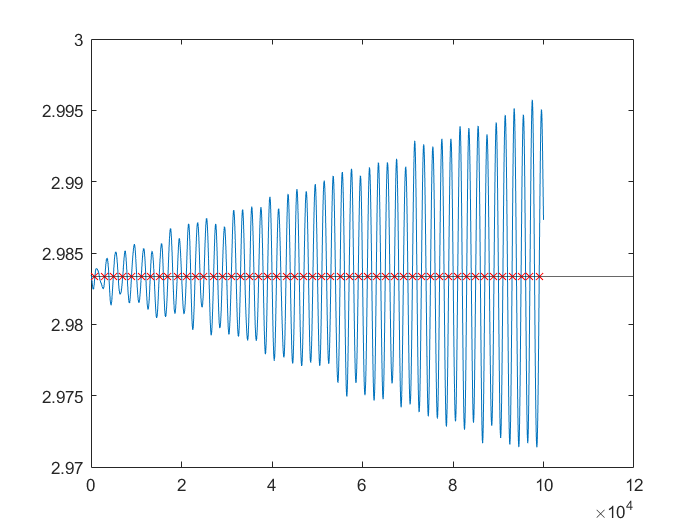

% function [I_spike_phase, II_spike_phase, III_spike_phase, I_spike, II_spike, III_spike] = spike_phase(stimulus, raster_data, fs, start_stim, stop_stim, stim_type, freq)

% resp = P(1).raster(:,start_stim+2*fs:stop_stim);
% stim = P(1).antennal_movement(:,start_stim+2*fs:stop_stim);

resp = P(1).raster(:,start_stim:stop_stim);
stim = P(1).antennal_movement(:,start_stim:stop_stim);
mean_pos = mean(stim(1,:));

locs = [];
zc = nan([1,length(stim)]);
for j = 2:length(stim)
    if (stim(1,j-1)<=mean_pos && stim(1,j)>=mean_pos && stim(1,j+1)>mean_pos)
        zc(j) = 1;
    end
end
locs = find(zc==1);

% figure;
% A1 =  subplot(2,1,1); 
figure;
plot(stim(1,:)); hold on; plot(locs, stim(1, locs), 'rx'); yline(mean_pos); hold off;

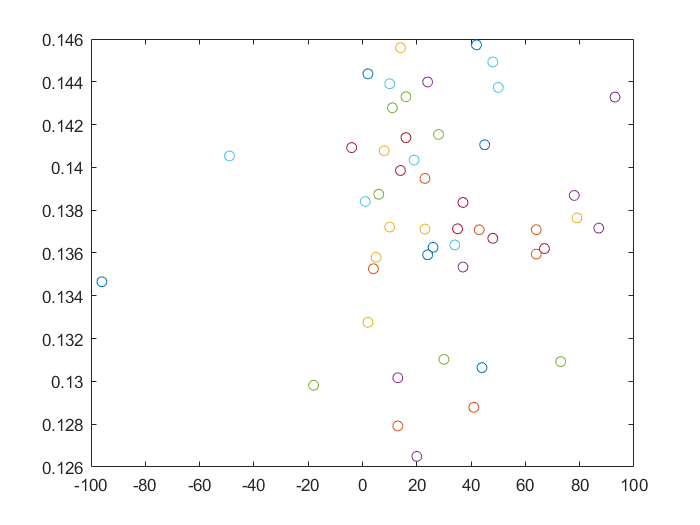


stim_clips = [];
resp_clips = [];
I_spike_phase = [];
amp_val = [];
spike_time_sd = [];

amp_val_list = [];
spike_time_list = [];

I = 1; 

figure;

for k= 2:length(locs)
    stim_clips = stim(1, locs(k-1):locs(k));
    resp_clips = resp(:, locs(k-1):locs(k));
    
    [r,lags] = xcorr(stim_clips, sum(resp_clips,1), 'normalized');
    [M,I] = max(r);
    plot(lags(I), M, 'o'); hold on;
    
    [row_ind,col_ind] = find(resp_clips == 1);
    
    
    [C, ia, ic] = unique(row_ind, 'stable');
    ind = col_ind(ia);
    
    
    
    
%         figure;
%         plot(stim_clips); hold on; plot(ind, stim_clips(ind), 'rx');
    
    if length(col_ind)>=1
        %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period(ind(1)));
        %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period(k-1));
        I_spike_time = ind/fs;
        if length(ind) == P(1).complete_trials
            spike_time_sd(I) = (std(I_spike_time));
            %             I_spike(I) = freq(ind(1)+locs(k-1));%stim_freq(k-1);
            amp_val(I) = max(stim_clips) - min(stim_clips);
            mean_spike_time(I) = mean(I_spike_time);
            
            if amp_val(I) > 0.01
                amp_val_list = [amp_val_list amp_val(I).*ones(1,length(ind))];
                spike_time_list = [spike_time_list (ind./fs)'];
                
%                 scatter(amp_val(I).*ones(1,length(ind)), ((ind./fs)'));
%                 hold on;
            end
            
            I=I+1;
                        
        end
    end
    
    
    
    %     elseif stim_type == "amp"
    %
    %         stim_period = 1/freq;
    % %         stim_freq = 1 ./ (diff(locs) / fs);
    % %         stim_period = 1./stim_freq;
    %
    %         if length(ind)>=1
    %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period);
    %             I_spike(I) = max(stim_clips) - min(stim_clips);
    %             I=I+1;
    %         end
    %
    %
    %     end
end


figure;
[f, gof] = fit(amp_val_list', spike_time_list', 'poly1')

f =      Linear model Poly1:
     f(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.2849  (-0.5079, -0.06193)
       p2 =     0.01371  (0.009744, 0.01767)

gof = struct with fields:
           sse: 0.0053
       rsquare: 0.0400
           dfe: 153
    adjrsquare: 0.0337
          rmse: 0.0059


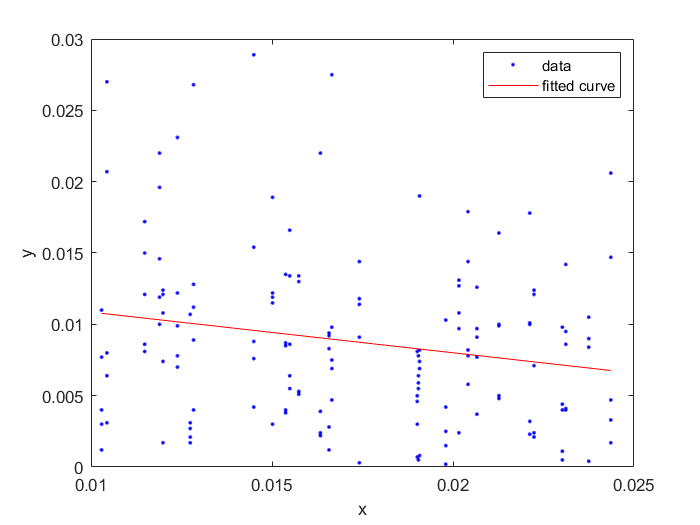

plot(f, amp_val_list, spike_time_list);


valid_amp_idx = find(amp_val > 0.01);
    
valid_amp = amp_val(valid_amp_idx);
valid_jitter_vals = (spike_time_sd(valid_amp_idx))*1000; %in ms
valid_mean_spike_time = mean_spike_time(valid_amp_idx);

figure;
% scatter(I_spike, spike_time_sd, 20, "filled")
% [f, gof] = fit(I_spike', spike_time_sd', 'poly1')
% plot(f, I_spike, spike_time_sd)

[f, gof] = fit(valid_amp', valid_jitter_vals', 'poly1')

f =      Linear model Poly1:
     f(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -110.5  (-293.1, 72.16)
       p2 =         7.3  (4.056, 10.54)

gof = struct with fields:
           sse: 125.4776
       rsquare: 0.0501
           dfe: 29
    adjrsquare: 0.0174
          rmse: 2.0801


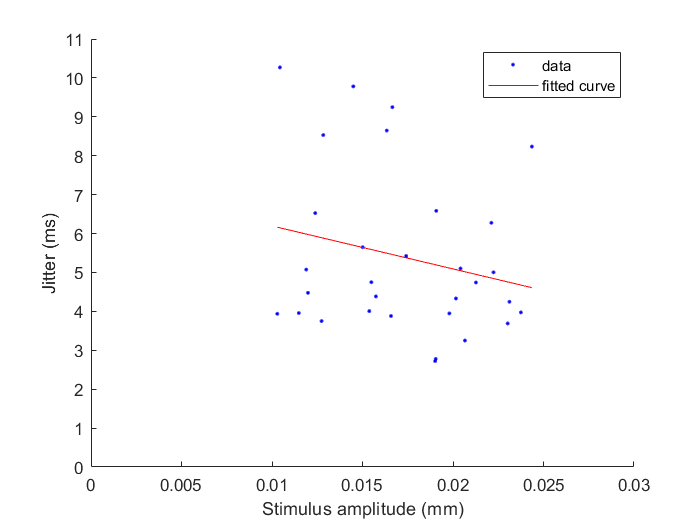

plot(f, valid_amp, valid_jitter_vals);

ylabel('Jitter (ms)');
xlabel('Stimulus amplitude (mm)')
xlim([0 0.03])
ylim([0 11])
box off;

% title(LUT_intra_row_idx)

meta_ampsweep_jitter(struct_id).LUT_idx = LUT_intra_row_idx;
meta_ampsweep_jitter(struct_id).amp = amp_val_list;
meta_ampsweep_jitter(struct_id).spike_times = spike_time_list;
struct_id = struct_id + 1

struct_id = 14